
addpath(genpath('test_signals'));
addpath(genpath('../effects'));
%% sine signal 


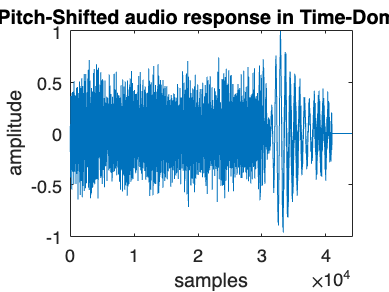


buff_length = 512;
[out, fs] = audioread('mono-file.mp3');
fs = 48000;
out = out(1:44100,1);
vocoder = PitchChangePlugin();

sat=Saturation();
%%
num_buffs = floor(length(out) / buff_length);
audio_out = zeros(size(out));

for b = 1:num_buffs
    start_ind = ((b - 1) * buff_length) + 1;
    end_ind = start_ind + (buff_length - 1);
    buff = out(start_ind:end_ind);
    %ess_out(start_ind:end_ind,:) = process();
end
out=vocoder.process(out);
figure(3);
plot(out);
title('Pitch-Shifted audio response in Time-Domain');
xlabel('samples');
ylabel('amplitude');

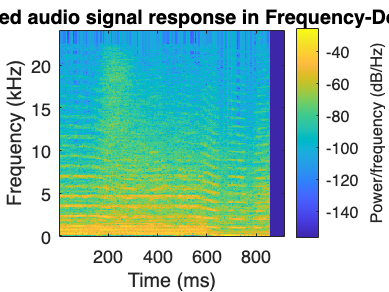


win_length = buff_length;
overlap_length = floor(win_length / 2);
nfft = max(256, 2^nextpow2(win_length));
figure(4);
spectrogram(out, hamming(win_length), overlap_length, nfft, fs, 'yaxis');
title('Pitch-Shifted audio signal response in Frequency-Domain');

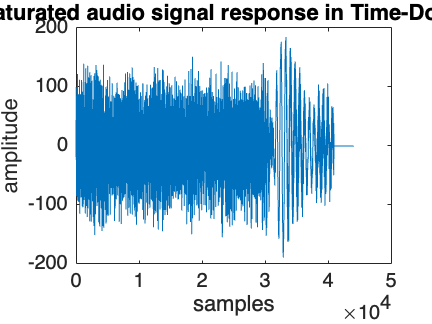


%soundsc(out, fs);

for b = 1:num_buffs
    start_ind = ((b - 1) * buff_length) + 1;
    end_ind = start_ind + (buff_length - 1);
    buff = out(start_ind:end_ind);
    audio_out(start_ind:end_ind,:) = sat.process(buff);
end

figure(3);
plot(audio_out);
title('Saturated audio signal response in Time-Domain');
xlabel('samples');
ylabel('amplitude');

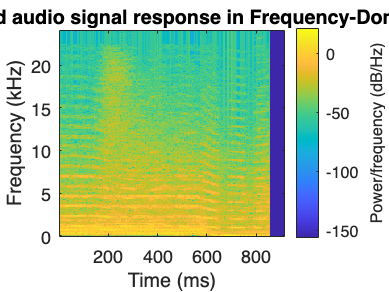



win_length = buff_length;
overlap_length = floor(win_length / 2);
nfft = max(256, 2^nextpow2(win_length));
figure(4);
spectrogram(audio_out, hamming(win_length), overlap_length, nfft, fs, 'yaxis');
title('Saturated audio signal response in Frequency-Domain');

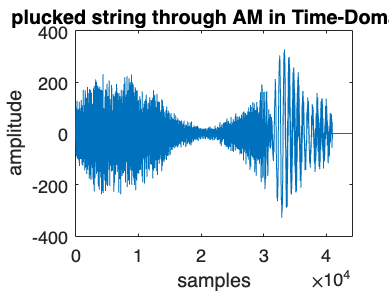


%soundsc(out, fs);

%amplitude modulation

Effect_out=zeros(length(audio_out),1);
amMod=AmplitudeModulation();
amMod.modulationFrequency=10;
amMod.modulationDepth=0.8;
for b = 1:num_buffs
    start_ind = ((b-1)*buff_length)+1;
    end_ind = start_ind + (buff_length-1);
    buff = audio_out(start_ind:end_ind);
    [Effect_out(start_ind:end_ind),amMod] = amMod.process(buff);
end

figure(1);
plot(Effect_out);
title('plucked string through AM in Time-Domain');
xlabel('samples');
ylabel('amplitude');

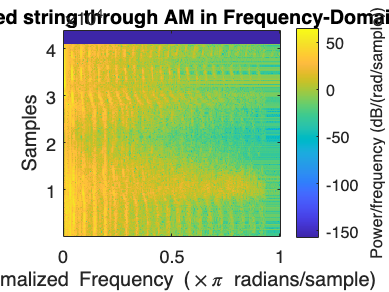

%soundsc(Effect_out,fs);

win_length = buff_length;
overlap_length = floor(win_length/2);
nfft = max(256,2^nextpow2(win_length));

figure(2);
spectrogram(Effect_out, hamming(win_length), overlap_length, nfft);
title('Plucked string through AM in Frequency-Domain');

%soundsc(Effect_out,fs);


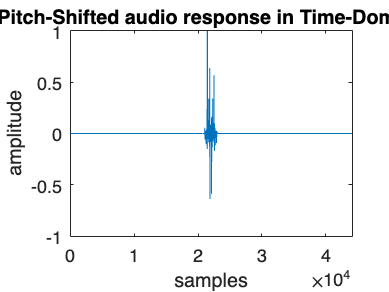

%Each test signals

% dirac

buff_length = 512;
[out, fs] = audioread('dirac_test.wav');
fs = 48000;
out = out(1:44100,1);
vocoder = PitchChangePlugin();

sat=Saturation();
%%
num_buffs = floor(length(out) / buff_length);
audio_out = zeros(size(out));

for b = 1:num_buffs
    start_ind = ((b - 1) * buff_length) + 1;
    end_ind = start_ind + (buff_length - 1);
    buff = out(start_ind:end_ind);
    %ess_out(start_ind:end_ind,:) = process();
end
out=vocoder.process(out);
figure(3);
plot(out);
title('Pitch-Shifted audio response in Time-Domain');
xlabel('samples');
ylabel('amplitude');

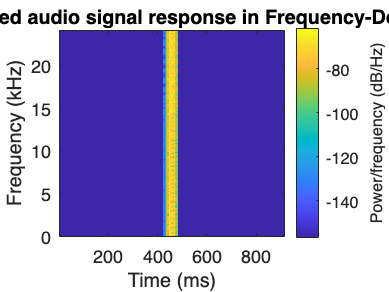


win_length = buff_length;
overlap_length = floor(win_length / 2);
nfft = max(256, 2^nextpow2(win_length));
figure(4);
spectrogram(out, hamming(win_length), overlap_length, nfft, fs, 'yaxis');
title('Pitch-Shifted audio signal response in Frequency-Domain');

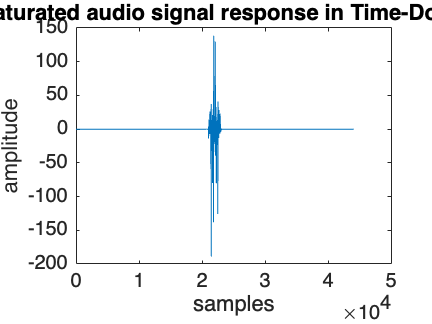


%soundsc(out, fs);

for b = 1:num_buffs
    start_ind = ((b - 1) * buff_length) + 1;
    end_ind = start_ind + (buff_length - 1);
    buff = out(start_ind:end_ind);
    audio_out(start_ind:end_ind,:) = sat.process(buff);
end

figure(3);
plot(audio_out);
title('Saturated audio signal response in Time-Domain');
xlabel('samples');
ylabel('amplitude');

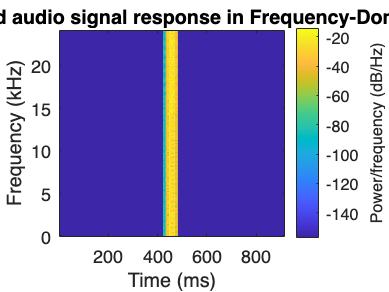



win_length = buff_length;
overlap_length = floor(win_length / 2);
nfft = max(256, 2^nextpow2(win_length));
figure(4);
spectrogram(audio_out, hamming(win_length), overlap_length, nfft, fs, 'yaxis');
title('Saturated audio signal response in Frequency-Domain');

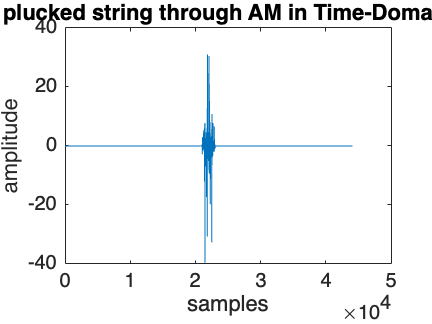


%soundsc(out, fs);

%amplitude modulation

Effect_out=zeros(length(audio_out),1);
amMod=AmplitudeModulation();
amMod.modulationFrequency=10;
amMod.modulationDepth=0.8;
for b = 1:num_buffs
    start_ind = ((b-1)*buff_length)+1;
    end_ind = start_ind + (buff_length-1);
    buff = audio_out(start_ind:end_ind);
    [Effect_out(start_ind:end_ind),amMod] = amMod.process(buff);
end

figure(1);
plot(Effect_out);
title('plucked string through AM in Time-Domain');
xlabel('samples');
ylabel('amplitude');

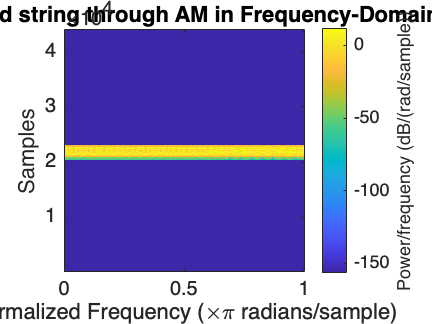

soundsc(Effect_out,fs);

win_length = buff_length;
overlap_length = floor(win_length/2);
nfft = max(256,2^nextpow2(win_length));

figure(2);
spectrogram(Effect_out, hamming(win_length), overlap_length, nfft);
title('Plucked string through AM in Frequency-Domain');

soundsc(Effect_out,fs);

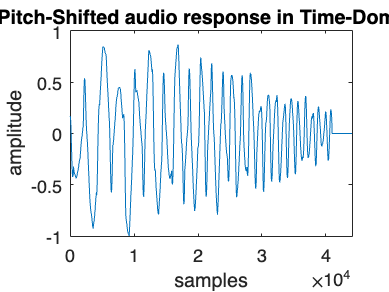

buff_length = 512;
[out, fs] = audioread('sinesweep_test.wav');
fs = 48000;
out = out(1:44100,1);
vocoder = PitchChangePlugin();

sat=Saturation();
%%
num_buffs = floor(length(out) / buff_length);
audio_out = zeros(size(out));

for b = 1:num_buffs
    start_ind = ((b - 1) * buff_length) + 1;
    end_ind = start_ind + (buff_length - 1);
    buff = out(start_ind:end_ind);
    %ess_out(start_ind:end_ind,:) = process();
end
out=vocoder.process(out);
figure(3);
plot(out);
title('Pitch-Shifted audio response in Time-Domain');
xlabel('samples');
ylabel('amplitude');

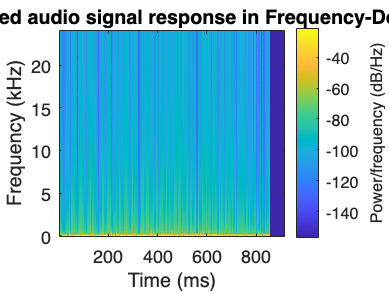


win_length = buff_length;
overlap_length = floor(win_length / 2);
nfft = max(256, 2^nextpow2(win_length));
figure(4);
spectrogram(out, hamming(win_length), overlap_length, nfft, fs, 'yaxis');
title('Pitch-Shifted audio signal response in Frequency-Domain');

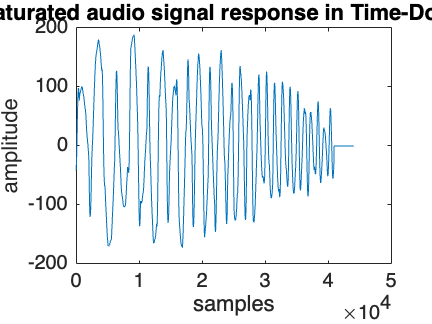


%soundsc(out, fs);

for b = 1:num_buffs
    start_ind = ((b - 1) * buff_length) + 1;
    end_ind = start_ind + (buff_length - 1);
    buff = out(start_ind:end_ind);
    audio_out(start_ind:end_ind,:) = sat.process(buff);
end

figure(3);
plot(audio_out);
title('Saturated audio signal response in Time-Domain');
xlabel('samples');
ylabel('amplitude');

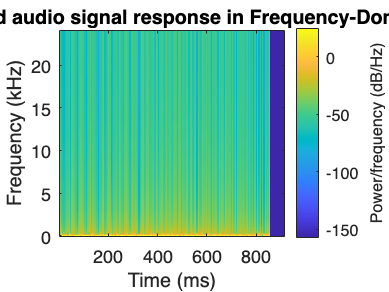



win_length = buff_length;
overlap_length = floor(win_length / 2);
nfft = max(256, 2^nextpow2(win_length));
figure(4);
spectrogram(audio_out, hamming(win_length), overlap_length, nfft, fs, 'yaxis');
title('Saturated audio signal response in Frequency-Domain');

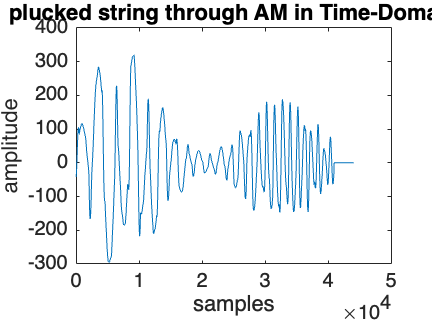


%soundsc(out, fs);

%amplitude modulation

Effect_out=zeros(length(audio_out),1);
amMod=AmplitudeModulation();
amMod.modulationFrequency=10;
amMod.modulationDepth=0.8;
for b = 1:num_buffs
    start_ind = ((b-1)*buff_length)+1;
    end_ind = start_ind + (buff_length-1);
    buff = audio_out(start_ind:end_ind);
    [Effect_out(start_ind:end_ind),amMod] = amMod.process(buff);
end

figure(1);
plot(Effect_out);
title('plucked string through AM in Time-Domain');
xlabel('samples');
ylabel('amplitude');

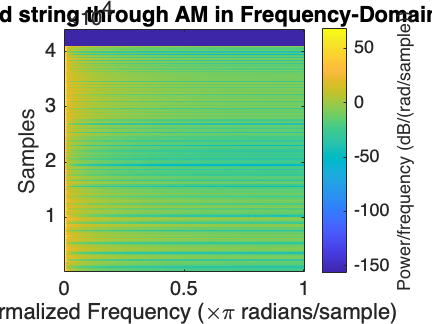

%soundsc(Effect_out,fs);

win_length = buff_length;
overlap_length = floor(win_length/2);
nfft = max(256,2^nextpow2(win_length));

figure(2);
spectrogram(Effect_out, hamming(win_length), overlap_length, nfft);
title('Plucked string through AM in Frequency-Domain');

%soundsc(Effect_out,fs);


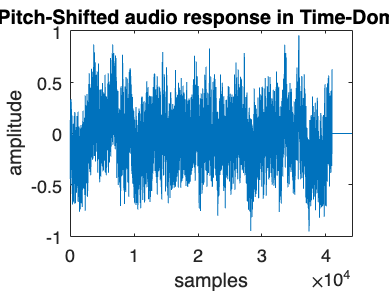

buff_length = 512;
[out, fs] = audioread('pinknoise_test.wav');
fs = 48000;
out = out(1:44100,1);
vocoder = PitchChangePlugin();

sat=Saturation();
%%
num_buffs = floor(length(out) / buff_length);
audio_out = zeros(size(out));

for b = 1:num_buffs
    start_ind = ((b - 1) * buff_length) + 1;
    end_ind = start_ind + (buff_length - 1);
    buff = out(start_ind:end_ind);
    %ess_out(start_ind:end_ind,:) = process();
end
out=vocoder.process(out);
figure(3);
plot(out);
title('Pitch-Shifted audio response in Time-Domain');
xlabel('samples');
ylabel('amplitude');

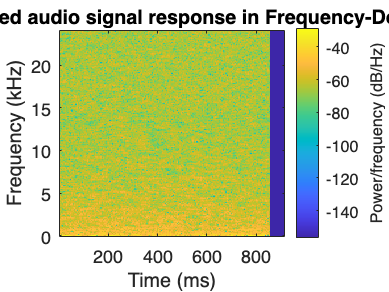


win_length = buff_length;
overlap_length = floor(win_length / 2);
nfft = max(256, 2^nextpow2(win_length));
figure(4);
spectrogram(out, hamming(win_length), overlap_length, nfft, fs, 'yaxis');
title('Pitch-Shifted audio signal response in Frequency-Domain');

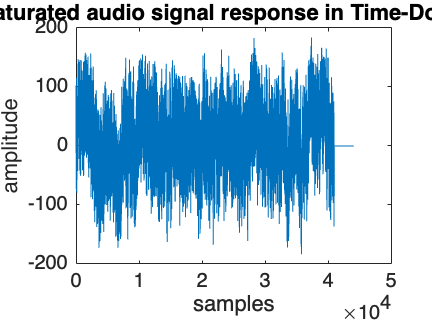


%soundsc(out, fs);

for b = 1:num_buffs
    start_ind = ((b - 1) * buff_length) + 1;
    end_ind = start_ind + (buff_length - 1);
    buff = out(start_ind:end_ind);
    audio_out(start_ind:end_ind,:) = sat.process(buff);
end

figure(3);
plot(audio_out);
title('Saturated audio signal response in Time-Domain');
xlabel('samples');
ylabel('amplitude');

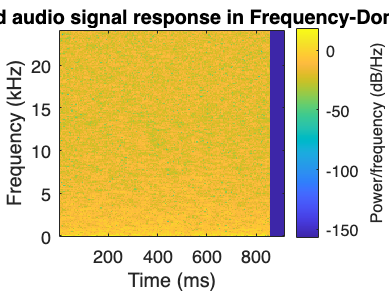



win_length = buff_length;
overlap_length = floor(win_length / 2);
nfft = max(256, 2^nextpow2(win_length));
figure(4);
spectrogram(audio_out, hamming(win_length), overlap_length, nfft, fs, 'yaxis');
title('Saturated audio signal response in Frequency-Domain');

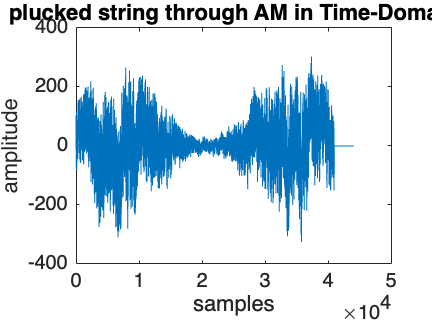


%soundsc(out, fs);

%amplitude modulation

Effect_out=zeros(length(audio_out),1);
amMod=AmplitudeModulation();
amMod.modulationFrequency=10;
amMod.modulationDepth=0.8;
for b = 1:num_buffs
    start_ind = ((b-1)*buff_length)+1;
    end_ind = start_ind + (buff_length-1);
    buff = audio_out(start_ind:end_ind);
    [Effect_out(start_ind:end_ind),amMod] = amMod.process(buff);
end

figure(1);
plot(Effect_out);
title('plucked string through AM in Time-Domain');
xlabel('samples');
ylabel('amplitude');

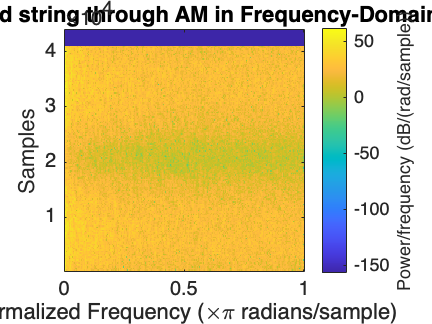

%soundsc(Effect_out,fs);

win_length = buff_length;
overlap_length = floor(win_length/2);
nfft = max(256,2^nextpow2(win_length));

figure(2);
spectrogram(Effect_out, hamming(win_length), overlap_length, nfft);
title('Plucked string through AM in Frequency-Domain');

%soundsc(Effect_out,fs);


%each test signals through pitch shift plugin
%%
%%
%%


%dirac
buff_length = 512;
[out, fs] = audioread('dirac_test.wav');
fs = 48000;
out = out(1:44100,1);
vocoder = PitchChangePlugin();

sat=Saturation();
%%
num_buffs = floor(length(out) / buff_length);
audio_out = zeros(size(out));

for b = 1:num_buffs
    start_ind = ((b - 1) * buff_length) + 1;
    end_ind = start_ind + (buff_length - 1);
    buff = out(start_ind:end_ind);
    %ess_out(start_ind:end_ind,:) = process();
end
out=vocoder.process(out);
figure(3);
plot(out);
title('Pitch-Shifted audio response in Time-Domain');
xlabel('samples');
ylabel('amplitude');

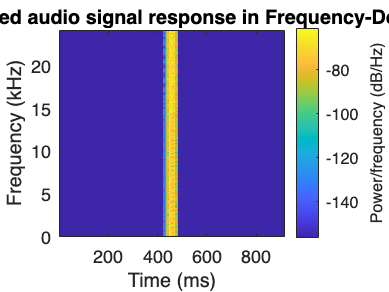


win_length = buff_length;
overlap_length = floor(win_length / 2);
nfft = max(256, 2^nextpow2(win_length));
figure(4);
spectrogram(out, hamming(win_length), overlap_length, nfft, fs, 'yaxis');
title('Pitch-Shifted audio signal response in Frequency-Domain');


%soundsc(out, fs);

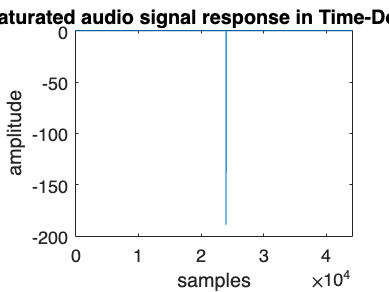




%delta
%saturation
sat=Saturation();
buff_length = 512;
[out, fs] = audioread('dirac_test.wav');
fs = 48000;

for b = 1:num_buffs
    start_ind = ((b - 1) * buff_length) + 1;
    end_ind = start_ind + (buff_length - 1);
    buff = out(start_ind:end_ind);
    audio_out(start_ind:end_ind,:) = sat.process(buff);
end

figure(3);
plot(audio_out);
title('Saturated audio signal response in Time-Domain');
xlabel('samples');
ylabel('amplitude');

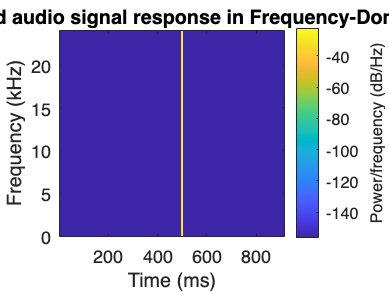



win_length = buff_length;
overlap_length = floor(win_length / 2);
nfft = max(256, 2^nextpow2(win_length));
figure(4);
spectrogram(audio_out, hamming(win_length), overlap_length, nfft, fs, 'yaxis');
title('Saturated audio signal response in Frequency-Domain');

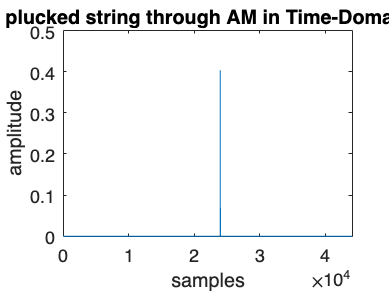

%dirac through Am
sat=Saturation();
buff_length = 512;
[out, fs] = audioread('dirac_test.wav');
fs = 48000;
Effect_out=zeros(length(audio_out),1);
amMod=AmplitudeModulation();
amMod.modulationFrequency=10;
amMod.modulationDepth=0.8;
for b = 1:num_buffs
    start_ind = ((b-1)*buff_length)+1;
    end_ind = start_ind + (buff_length-1);
    buff = out(start_ind:end_ind);
    [Effect_out(start_ind:end_ind),amMod] = amMod.process(buff);
end

figure(1);
plot(Effect_out);
title('plucked string through AM in Time-Domain');
xlabel('samples');
ylabel('amplitude');

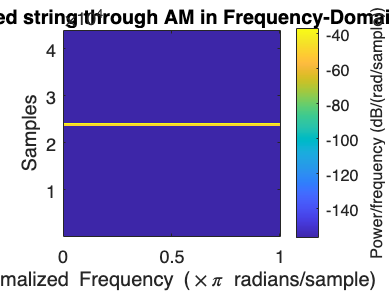

%soundsc(Effect_out,fs);

win_length = buff_length;
overlap_length = floor(win_length/2);
nfft = max(256,2^nextpow2(win_length));

figure(2);
spectrogram(Effect_out, hamming(win_length), overlap_length, nfft);
title('Plucked string through AM in Frequency-Domain');

%soundsc(Effect_out,fs);


%%


%sinesweep



buff_length = 512;
[out, fs] = audioread('sinesweep_test.wav');
fs = 48000;
out = out(1:44100,1);
vocoder = PitchChangePlugin();

sat=Saturation();
%%
num_buffs = floor(length(out) / buff_length);
audio_out = zeros(size(out));

for b = 1:num_buffs
    start_ind = ((b - 1) * buff_length) + 1;
    end_ind = start_ind + (buff_length - 1);
    buff = out(start_ind:end_ind);
    %ess_out(start_ind:end_ind,:) = process();
end
out=vocoder.process(out);
figure(3);
plot(out);
title('Pitch-Shifted audio response in Time-Domain');
xlabel('samples');
ylabel('amplitude');

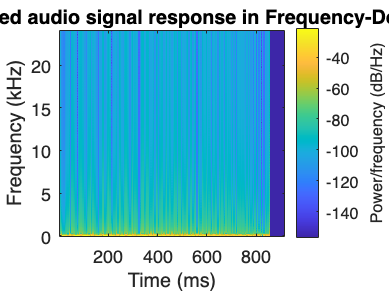


win_length = buff_length;
overlap_length = floor(win_length / 2);
nfft = max(256, 2^nextpow2(win_length));
figure(4);
spectrogram(out, hamming(win_length), overlap_length, nfft, fs, 'yaxis');
title('Pitch-Shifted audio signal response in Frequency-Domain');


%soundsc(out, fs);

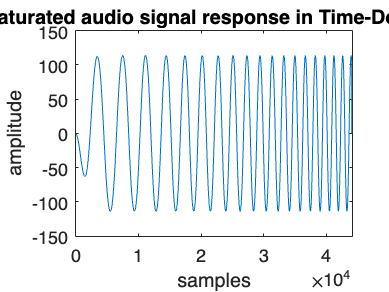



%sinesweep 
%saturation
sat=Saturation();
buff_length = 512;
[out, fs] = audioread('sinesweep_test.wav');
fs = 48000;

for b = 1:num_buffs
    start_ind = ((b - 1) * buff_length) + 1;
    end_ind = start_ind + (buff_length - 1);
    buff = out(start_ind:end_ind);
    audio_out(start_ind:end_ind,:) = sat.process(buff);
end

figure(3);
plot(audio_out);
title('Saturated audio signal response in Time-Domain');
xlabel('samples');
ylabel('amplitude');

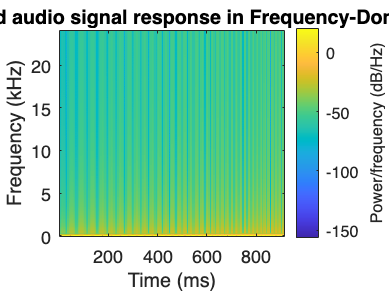



win_length = buff_length;
overlap_length = floor(win_length / 2);
nfft = max(256, 2^nextpow2(win_length));
figure(4);
spectrogram(audio_out, hamming(win_length), overlap_length, nfft, fs, 'yaxis');
title('Saturated audio signal response in Frequency-Domain');

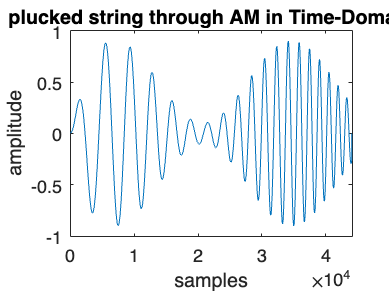

%sinesweep through Am

buff_length = 512;
[out, fs] = audioread('sinesweep_test.wav');
fs = 48000;
Effect_out=zeros(length(audio_out),1);
amMod=AmplitudeModulation();
amMod.modulationFrequency=10;
amMod.modulationDepth=0.8;
for b = 1:num_buffs
    start_ind = ((b-1)*buff_length)+1;
    end_ind = start_ind + (buff_length-1);
    buff = out(start_ind:end_ind);
    [Effect_out(start_ind:end_ind),amMod] = amMod.process(buff);
end

figure(1);
plot(Effect_out);
title('plucked string through AM in Time-Domain');
xlabel('samples');
ylabel('amplitude');

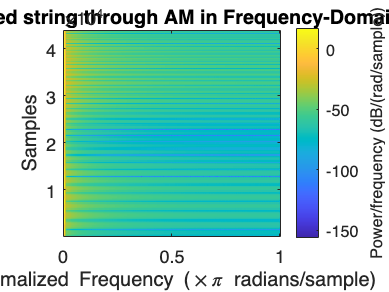

%soundsc(Effect_out,fs);

win_length = buff_length;
overlap_length = floor(win_length/2);
nfft = max(256,2^nextpow2(win_length));

figure(2);
spectrogram(Effect_out, hamming(win_length), overlap_length, nfft);
title('Plucked string through AM in Frequency-Domain');

%soundsc(Effect_out,fs);


%%

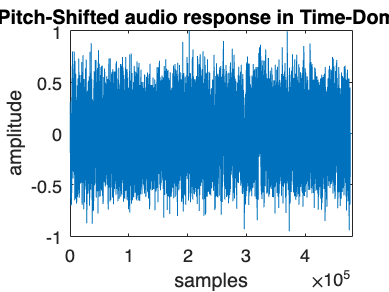

%pinknoise_test.wav
buff_length = 512;
[out, fs] = audioread('pinknoise_test.wav');
fs = 48000;

vocoder = PitchChangePlugin();

sat=Saturation();
%%
num_buffs = floor(length(out) / buff_length);
audio_out = zeros(size(out));

for b = 1:num_buffs
    start_ind = ((b - 1) * buff_length) + 1;
    end_ind = start_ind + (buff_length - 1);
    buff = out(start_ind:end_ind);
    %ess_out(start_ind:end_ind,:) = process();
end
out=vocoder.process(out);
figure(3);
plot(out);
title('Pitch-Shifted audio response in Time-Domain');
xlabel('samples');
ylabel('amplitude');

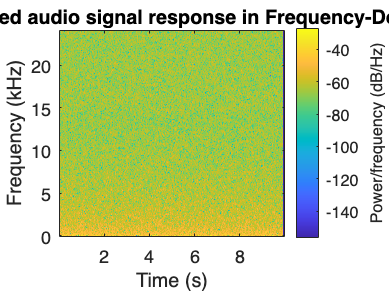


win_length = buff_length;
overlap_length = floor(win_length / 2);
nfft = max(256, 2^nextpow2(win_length));
figure(4);
spectrogram(out, hamming(win_length), overlap_length, nfft, fs, 'yaxis');
title('Pitch-Shifted audio signal response in Frequency-Domain');


%soundsc(out, fs);

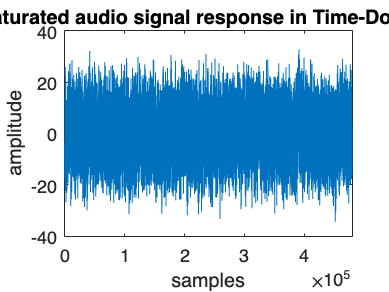



%pinknoise_test.wav 
%saturation
sat=Saturation();
buff_length = 512;
[out, fs] = audioread('pinknoise_test.wav');
fs = 48000;

for b = 1:num_buffs
    start_ind = ((b - 1) * buff_length) + 1;
    end_ind = start_ind + (buff_length - 1);
    buff = out(start_ind:end_ind);
    audio_out(start_ind:end_ind,:) = sat.process(buff);
end

figure(3);
plot(audio_out);
title('Saturated audio signal response in Time-Domain');
xlabel('samples');
ylabel('amplitude');

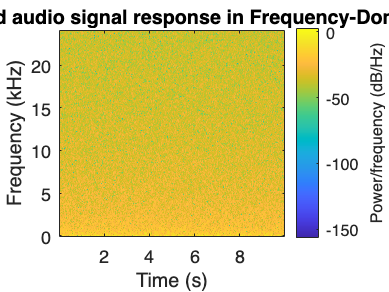



win_length = buff_length;
overlap_length = floor(win_length / 2);
nfft = max(256, 2^nextpow2(win_length));
figure(4);
spectrogram(audio_out, hamming(win_length), overlap_length, nfft, fs, 'yaxis');
title('Saturated audio signal response in Frequency-Domain');

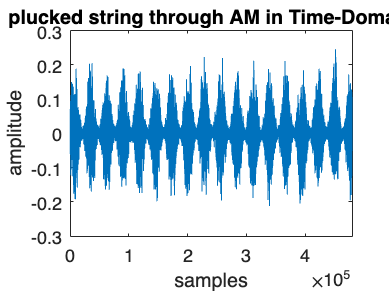

%pinknoise_test.wav through Am

buff_length = 512;
[out, fs] = audioread('pinknoise_test.wav');
fs = 48000;
Effect_out=zeros(length(audio_out),1);
amMod=AmplitudeModulation();
amMod.modulationFrequency=10;
amMod.modulationDepth=0.8;
for b = 1:num_buffs
    start_ind = ((b-1)*buff_length)+1;
    end_ind = start_ind + (buff_length-1);
    buff = out(start_ind:end_ind);
    [Effect_out(start_ind:end_ind),amMod] = amMod.process(buff);
end

figure(1);
plot(Effect_out);
title('plucked string through AM in Time-Domain');
xlabel('samples');
ylabel('amplitude');

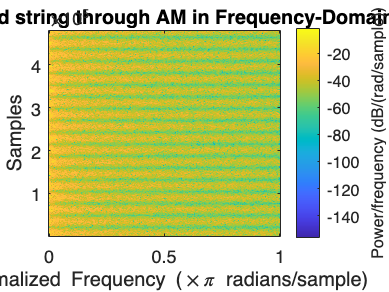

%soundsc(Effect_out,fs);

win_length = buff_length;
overlap_length = floor(win_length/2);
nfft = max(256,2^nextpow2(win_length));

figure(2);
spectrogram(Effect_out, hamming(win_length), overlap_length, nfft);
title('Plucked string through AM in Frequency-Domain');

%soundsc(Effect_out,fs);


%%